clear all; close all; clc;

1.1. About the specifications of the dataset

data = readtable('sensor_readings_24.dat');
labels = data(:,25);
features = data(:,1:24);
features = table2array(features);

[rowf,colf] = size(features);
m_feat = mean(features);
std_feat = std(features);
max_feat = max(features);
min_feat = min(features);
normtype = 'z-score';
norm_feat = [];
switch(normtype)
    case 'none'
    case 'z-score'
        for i=1:1:rowf
            norm_feat(i,:) = (features(i,:)-m_feat)./std_feat;
        end
        features = norm_feat;
    case 'range1'
        for i=1:1:rowf
            norm_feat(i,:) = (features(i,:)-min_feat)./(max_feat-min_feat);
        end
        features = norm_feat;
end

% for i=1:1:colf
%     figure
%     histogram(features(:,i))
% end
% maxval = max(features)
% minval = min(features)
aux = table2cell(labels);
labels = [];

for i=1:1:length(aux)
    labels{i,1} = cell2mat(aux(i));
end

% Name of the classes
uni_labels = unique(unique(labels))

uni_labels = 4×1 cell array
    {'Move-Forward'     }
    {'Sharp-Right-Turn' }
    {'Slight-Left-Turn' }
    {'Slight-Right-Turn'}


% Total of classes
num_labels = length(uni_labels)

num_labels = 4

group = [];
names = [];
for i=1:1:length(uni_labels)
    names = [names; ['class' num2str(i,'%d')]];
    cont = 1;
    char1 = uni_labels{i};
    for j=1:1:length(labels)
        char2 = labels{j};
        TF = strcmp(char1,char2);
        if TF
            group{cont,i} = features(j,:);
            pos{cont,i} = j;
            cont = cont+1;
        end
    end
    num_ele(i) = cont-1;
end

% Number of instances in each class
num_ele

num_ele =         2205        2097         328         826


[row,col] = size(group);

for i=1:1:col
    aux1 = [];
    for j=1:1:num_ele(i)
        aux1(j,:) = group{j,i}; 
    end
    eval([names(i,:) '= aux1;']);
    na(i) = convertCharsToStrings(names(i,:));
end

% Feature dimension - p
row = size(features,2)

row = 24

02. Evaluate the covariance matrices and its inverter

na = ["features", na];
na = na';

for i=1:1:size(na,1)
    aux = [];
    m = [];
    aux = eval(na(i,:))';
    [r c] = size(aux);
    m = mymean(eval(na(i)));
    m = m';
    N(i) = c;

    M = zeros(r,c);
    for j=1:1:c
        M(:,j) = m;
    end
    aux1 = (1/(c-1))*((aux-M)*(aux-M)');
    C{i} = aux1;

    val(i,1) = rank(aux1);
    val(i,2) = rcond(aux1);
end

lambda = 0.01;
for i=1:1:length(C)
    Creg{i} = C{i} + lambda*eye(r);
    regval(i,1) = rank(Creg{i});
    regval(i,2) = rcond(Creg{i});
end

% Rank and Condition number without regularization
val

val =    24.0000    0.0352
   24.0000    0.0164
   24.0000    0.0219
   24.0000    0.0018
   24.0000    0.0031


% Rank and Condition number - Tikhonov regularization
regval

regval =    24.0000    0.0361
   24.0000    0.0173
   24.0000    0.0227
   24.0000    0.0030
   24.0000    0.0038


**CLASSIFIERS**

**Classificador quadrático gaussiano - Mahalanobis with one COV matrix per class**

tic
num_r = 100;
prtrain = 0.3;
num_tr = round(N(1)*prtrain);
num_te = N(1) - num_tr;
aux3 = [];

class_ok = 0;
class1_ok = 0;
class2_ok = 0;
class3_ok = 0;
class4_ok = 0;

for k=1:1:num_r
    P = randperm(N(1),num_tr);
    P = sort(P);

    cont = 1;
    ct = 1;
    num = P(cont);

    for j=1:1:N(1)
        if num==j
            training(cont,:) = features(j,:);
            la_tr{cont,:} = labels{j,:};
            cont = cont+1;
            if cont <= length(P)
                num = P(cont);
            else 
                cont = length(P);
            end
        else 
            testing(ct,:) = features(j,:);
            la_ts{ct,:} = labels{j,:};
            ct = ct+1;
        end
    end

    % Training phase
    for i=1:num_labels
        aux3 = [];
        cont = 1;
        char1 = uni_labels{i};
        for u=1:1:num_tr
            char2 = la_tr{u};
            TF = strcmp(char1,char2);
            if TF
                aux3(cont,:) = training(u,:);
                cont = cont+1;
            end
        end

        n_class(i) = cont-1;
        class{i} = aux3;
        [C_cqg{i},Ci_cqg{i},m_cqg{i},val_cqg(i,:)] = mycov(aux3);
    end
    
    % Testing phase
    n_cor = 0;
    n1_ok = 0;
    n2_ok = 0;
    n3_ok = 0;
    n4_ok = 0;
    for v=1:1:num_te
        for t=1:1:num_labels
            sub = (testing(v,:)-m_cqg{t})';
            d(t,:) = sub'*Ci_cqg{t}*sub;
        end
        [dmin,I] = min(d);
        class{I} = [class{I}; testing(v,:)];
        char1 = la_ts(v);
        char2 = uni_labels{I};
        TF = strcmp(char1,char2);
            if TF
                n_cor = n_cor+1;
                if strcmp(char1,uni_labels{1})
                    n1_ok = n1_ok+1;
                end
                if strcmp(char1,uni_labels{2})
                    n2_ok = n2_ok+1;
                end
                if strcmp(char1,uni_labels{3})
                    n3_ok = n3_ok+1;
                end
                if strcmp(char1,uni_labels{4})
                    n4_ok = n4_ok+1;
                end
            end 
    end
    lab = zeros(length(la_ts),1);
    for i=1:num_labels
        char1 = uni_labels{i};
        for j=1:1:length(la_ts)
            char2 = la_ts{j};
            TF = strcmp(char1,char2);
            if TF
                lab(j) = i;
            end
        end
    end

    c1 = length(find(lab==1));
    c2 = length(find(lab==2));
    c3 = length(find(lab==3));
    c4 = length(find(lab==4));
    class1_ok(k)=100*n1_ok/c1;
    class2_ok(k)=100*n2_ok/c2;
    class3_ok(k)=100*n3_ok/c3;
    class4_ok(k)=100*n4_ok/c4;
    class_ok(k)=100*n_cor/num_te;
end

lab = zeros(length(labels),1);
for i=1:num_labels
    char1 = uni_labels{i};
    for j=1:1:length(labels)
        char2 = labels{j};
        TF = strcmp(char1,char2);
        if TF
            lab(j) = i;
        end
    end
end

data = [features lab];
Ptrain = 100*prtrain;
[STATS TX X m S posto]=quadratico(data,num_r,Ptrain);

The problem has 4 classes


% Comparison of the number of correct classifications
cmp = [mean(class_ok) std(class_ok);mean(TX) std(TX)]

cmp =    69.3490    0.8833
   69.1715    1.2606


% Comparison of the number of correct classifications for each class
cmp_class = [mean(class1_ok) std(class1_ok);mean(class2_ok) std(class2_ok);
    mean(class3_ok) std(class3_ok);mean(class4_ok) std(class4_ok)]

cmp_class =    65.9326    2.5007
   87.1996    2.1709
   48.6943    5.1120
   41.3230    3.8029


**Classificador quadrático gaussiano variante 2 - Mahalanobis with a common pooled covariance matrix**

class_ok = 0;
class1_ok = 0;
class2_ok = 0;
class3_ok = 0;
class4_ok = 0;
TX = 0;

for k=1:1:num_r
    P = randperm(N(1),num_tr);
    P = sort(P);

    cont = 1;
    ct = 1;
    num = P(cont);

    for j=1:1:N(1)
        if num==j
            training(cont,:) = features(j,:);
            la_tr{cont,:} = labels{j,:};
            cont = cont+1;
            if cont <= length(P)
                num = P(cont);
            else 
                cont = length(P);
            end
        else 
            testing(ct,:) = features(j,:);
            la_ts{ct,:} = labels{j,:};
            ct = ct+1;
        end
    end

    % Training phase
    Cpool = zeros(r);
    for i=1:num_labels
        aux3 = [];
        cont = 1;
        char1 = uni_labels{i};
        for u=1:1:num_tr
            char2 = la_tr{u};
            TF = strcmp(char1,char2);
            if TF
                aux3(cont,:) = training(u,:);
                cont = cont+1;
            end
        end

        n_class(i) = cont-1;
        class{i} = aux3;
        [C_cqg2{i},m_cqg2{i},val_cqg2(i,:)] = mycov2(aux3);
        Ni = size(aux3,1);
        
        Cpool = Cpool + (Ni)*C_cqg2{i};  
    end
    
    C_cqg2{num_labels+1} = Cpool/num_tr;
    aux4 = C_cqg2{num_labels+1};
    Ci_cqg2 = pinv(C_cqg2{num_labels+1});

    
    % Testing phase
    n_cor = 0;
    n1_ok = 0;
    n2_ok = 0;
    n3_ok = 0;
    n4_ok = 0;
    Cpool = zeros(r);
    for v=1:1:num_te
        for t=1:1:num_labels
            sub = (testing(v,:)-m_cqg{t})';
            d(t,:) = sub'*Ci_cqg2*sub;
        end
        [dmin,I] = min(d);
        class{I} = [class{I}; testing(v,:)];
        char1 = la_ts(v);
        char2 = uni_labels{I};
        TF = strcmp(char1,char2);
            if TF
                n_cor = n_cor+1;
                if strcmp(char1,uni_labels{1})
                    n1_ok = n1_ok+1;
                end
                if strcmp(char1,uni_labels{2})
                    n2_ok = n2_ok+1;
                end
                if strcmp(char1,uni_labels{3})
                    n3_ok = n3_ok+1;
                end
                if strcmp(char1,uni_labels{4})
                    n4_ok = n4_ok+1;
                end
            end  
    end

    lab = zeros(length(la_ts),1);
    for i=1:num_labels
        char1 = uni_labels{i};
        for j=1:1:length(la_ts)
            char2 = la_ts{j};
            TF = strcmp(char1,char2);
            if TF
                lab(j) = i;
            end
        end
    end

    c1 = length(find(lab==1));
    c2 = length(find(lab==2));
    c3 = length(find(lab==3));
    c4 = length(find(lab==4));
    class1_ok(k)=100*n1_ok/c1;
    class2_ok(k)=100*n2_ok/c2;
    class3_ok(k)=100*n3_ok/c3;
    class4_ok(k)=100*n4_ok/c4;
    class_ok(k)=100*n_cor/num_te;
end

lab = zeros(length(labels),1);
for i=1:num_labels
    char1 = uni_labels{i};
    for j=1:1:length(labels)
        char2 = labels{j};
        TF = strcmp(char1,char2);
        if TF
            lab(j) = i;
        end
    end
end


data = [features lab];
Ptrain = 100*prtrain;
[STATS TX X m S posto]=variante2(data,num_r,Ptrain);            

The problem has 4 classes


% Comparison of the number of correct classifications
cmp = [mean(class_ok) std(class_ok);mean(TX) std(TX)]    

cmp =    62.2660    0.6150
   61.2773    0.8941


% Comparison of the number of correct classifications for each class
cmp_class = [mean(class1_ok) std(class1_ok);mean(class2_ok) std(class2_ok);
    mean(class3_ok) std(class3_ok);mean(class4_ok) std(class4_ok)]

cmp_class =    55.5743    1.1242
   68.1869    1.1238
   88.6054    1.4439
   54.6464    2.2683


**Classificador quadrático gaussiano variante 4 - Mahalanobis with diagonal COV matrix (per class)**

class_ok = 0;
class1_ok = 0;
class2_ok = 0;
class3_ok = 0;
class4_ok = 0;
TX = 0;

for k=1:1:num_r
    P = randperm(N(1),num_tr);
    P = sort(P);

    cont = 1;
    ct = 1;
    num = P(cont);

    for j=1:1:N(1)
        if num==j
            training(cont,:) = features(j,:);
            la_tr{cont,:} = labels{j,:};
            cont = cont+1;
            if cont <= length(P)
                num = P(cont);
            else 
                cont = length(P);
            end
        else 
            testing(ct,:) = features(j,:);
            la_ts{ct,:} = labels{j,:};
            ct = ct+1;
        end
    end

    % Training phase
    for i=1:num_labels
        aux3 = [];
        cont = 1;
        char1 = uni_labels{i};
        for u=1:1:num_tr
            char2 = la_tr{u};
            TF = strcmp(char1,char2);
            if TF
                aux3(cont,:) = training(u,:);
                cont = cont+1;
            end
        end

        n_class(i) = cont-1;
        class{i} = aux3;
        [C_cqg4{i},Ci_cqg4{i},m_cqg4{i},val_cqg4(i,:)] = mycov4(aux3);
        std_cqg4{i} = std(aux3);
    end
    
    % Testing phase
    n_cor = 0;
    n1_ok = 0;
    n2_ok = 0;
    n3_ok = 0;
    n4_ok = 0;
    for v=1:1:num_te
        for t=1:1:num_labels
            sub = (testing(v,:)-m_cqg{t})';
            d(t,:) = sub'*Ci_cqg4{t}*sub;
        end
        [dmin,I] = min(d);
        class{I} = [class{I}; testing(v,:)];
        char1 = la_ts(v);
        char2 = uni_labels{I};
        TF = strcmp(char1,char2);
            if TF
                n_cor = n_cor+1;
                if strcmp(char1,uni_labels{1})
                    n1_ok = n1_ok+1;
                end
                if strcmp(char1,uni_labels{2})
                    n2_ok = n2_ok+1;
                end
                if strcmp(char1,uni_labels{3})
                    n3_ok = n3_ok+1;
                end
                if strcmp(char1,uni_labels{4})
                    n4_ok = n4_ok+1;
                end
            end 
    end
    lab = zeros(length(la_ts),1);
    for i=1:num_labels
        char1 = uni_labels{i};
        for j=1:1:length(la_ts)
            char2 = la_ts{j};
            TF = strcmp(char1,char2);
            if TF
                lab(j) = i;
            end
        end
    end

    c1 = length(find(lab==1));
    c2 = length(find(lab==2));
    c3 = length(find(lab==3));
    c4 = length(find(lab==4));
    class1_ok(k)=100*n1_ok/c1;
    class2_ok(k)=100*n2_ok/c2;
    class3_ok(k)=100*n3_ok/c3;
    class4_ok(k)=100*n4_ok/c4;
    class_ok(k)=100*n_cor/num_te;
end

lab = zeros(length(labels),1);
for i=1:num_labels
    char1 = uni_labels{i};
    for j=1:1:length(labels)
        char2 = labels{j};
        TF = strcmp(char1,char2);
        if TF
            lab(j) = i;
        end
    end
end

data = [features lab];
Ptrain = 100*prtrain;
[STATS TX X m S posto]=variante4(data,num_r,Ptrain);

The problem has 4 classes


% Comparison of the number of correct classifications
cmp = [mean(class_ok) std(class_ok);mean(TX) std(TX)] 

cmp =    62.5088    0.7059
   62.0731    0.8876


% Comparison of the number of correct classifications for each class
cmp_class = [mean(class1_ok) std(class1_ok);mean(class2_ok) std(class2_ok);
    mean(class3_ok) std(class3_ok);mean(class4_ok) std(class4_ok)]

cmp_class =    53.5704    2.1125
   80.1637    1.8120
   75.1562    4.8851
   36.4006    1.9088


**Classificador Linear de Mínimos Quadrados - Euclidean distance to the centroid (mean) of each class**

class_ok = 0;
class1_ok = 0;
class2_ok = 0;
class3_ok = 0;
class4_ok = 0;
TX = 0;

for k=1:1:num_r
    P = randperm(N(1),num_tr);
    P = sort(P);

    cont = 1;
    ct = 1;
    num = P(cont);

    for j=1:1:N(1)
        if num==j
            training(cont,:) = features(j,:);
            la_tr{cont,:} = labels{j,:};
            cont = cont+1;
            if cont <= length(P)
                num = P(cont);
            else 
                cont = length(P);
            end
        else 
            testing(ct,:) = features(j,:);
            la_ts{ct,:} = labels{j,:};
            ct = ct+1;
        end
    end

    % Training phase
    n_labels = eye(num_labels);
    X_tr = [];
    X_la = [];
    for i=1:num_labels
        aux3 = [];
        n_la = [];
        cont = 1;
        char1 = uni_labels{i};
        for u=1:1:num_tr
            char2 = la_tr{u};
            TF = strcmp(char1,char2);
            if TF
                aux3(cont,:) = training(u,:);
                n_la(cont,:) = n_labels(i,:);
                cont = cont+1;
            end
        end

        class{i} = aux3;
        nlabels{i} = n_la;
        X_tr = [X_tr;aux3];
        X_la = [X_la;n_la];
    end

    W=pinv(X_tr)*X_la;
    
    % Testing phase
    n_cor = 0;
    n1_ok = 0;
    n2_ok = 0;
    n3_ok = 0;
    n4_ok = 0;
    for v=1:1:num_te
        X_ts = testing(v,:);
        Y_ts = X_ts*W;
        
        [dmax,I] = max(Y_ts);

        class{I} = [class{I}; X_ts];
        nlabels{I} = [nlabels{I}; n_labels(I,:)];
        char1 = la_ts(v);
        char2 = uni_labels{I};
        TF = strcmp(char1,char2);
            if TF
                n_cor = n_cor+1;
                if strcmp(char1,uni_labels{1})
                    n1_ok = n1_ok+1;
                end
                if strcmp(char1,uni_labels{2})
                    n2_ok = n2_ok+1;
                end
                if strcmp(char1,uni_labels{3})
                    n3_ok = n3_ok+1;
                end
                if strcmp(char1,uni_labels{4})
                    n4_ok = n4_ok+1;
                end
            end 
    end
    lab = zeros(length(la_ts),1);
    for i=1:num_labels
        char1 = uni_labels{i};
        for j=1:1:length(la_ts)
            char2 = la_ts{j};
            TF = strcmp(char1,char2);
            if TF
                lab(j) = i;
            end
        end
    end

    c1 = length(find(lab==1));
    c2 = length(find(lab==2));
    c3 = length(find(lab==3));
    c4 = length(find(lab==4));
    class1_ok(k)=100*n1_ok/c1;
    class2_ok(k)=100*n2_ok/c2;
    class3_ok(k)=100*n3_ok/c3;
    class4_ok(k)=100*n4_ok/c4;
    class_ok(k)=100*n_cor/num_te;
end

lab = zeros(length(labels),1);
for i=1:num_labels
    char1 = uni_labels{i};
    for j=1:1:length(labels)
        char2 = labels{j};
        TF = strcmp(char1,char2);
        if TF
            lab(j) = i;
        end
    end
end

data = [features lab];
Ptrain = 100*prtrain;
[STATS TX W]=linearMQ(data,num_r,Ptrain,'none');

No data normalization!
The problem has 4 classes


% Comparison of the number of correct classifications
cmp = [mean(class_ok) std(class_ok);mean(TX) std(TX)] 

cmp =    63.8442    0.8511
   63.5216    0.8346


% Comparison of the number of correct classifications for each class
cmp_class = [mean(class1_ok) std(class1_ok);mean(class2_ok) std(class2_ok);
    mean(class3_ok) std(class3_ok);mean(class4_ok) std(class4_ok)]

cmp_class =    59.2473    1.6276
   72.0930    1.8225
   75.8727    4.5156
   50.5520    2.8557


tfinal = toc

tfinal = 244.3469

02. PCA

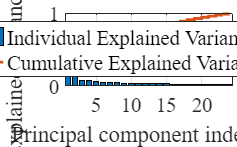

% First step
m=mean(features);
[rpca cpca] = size(features);
M = zeros(rpca,cpca);
for j=1:1:rpca
    M(j,:) = m;
end
n_fea = features - M;
Cx = cov(n_fea);

[U D V] = svd(Cx);
D = diag(D);

% Third Step
aux = 0;
for i=1:1:length(D)
    VEi(i) = D(i)/sum(D);
    VE(i) = aux+VEi(i);
    aux = VE(i);
end
VEi = VEi';
VE = VE';

X = n_fea';

plotVE(VEi, VE, 'Principal component index (q)', 'Explained variance ratio', ["Individual Explained Variance - VEi","Cumulative Explained Variance - VE(q)"])

% PCA dimension reduction
tol = 0.95;
q = find(VE<=tol);
Vq = V(:,q);
Q = Vq';
Z = Q*X;
Cz = cov(Z');
Xr = Q'*Z;

% Number of the q components
length(q)

ans = 20


features

features =    -1.2875   -1.2971    0.9104    0.6480    1.5244    0.0194    1.1664   -0.1704   -0.5849   -0.1448   -0.6160   -0.3128   -0.3040   -0.3003   -0.2692   -0.5545   -0.5178   -0.4691   -0.4841   -0.5531   -0.6591   -0.8488   -0.8634   -0.9992
   -1.2875   -1.2971    0.9104    0.6503    1.5244    0.0194    1.1664    0.0869   -0.5849   -0.1402   -0.6182   -0.3128   -0.3061   -0.2984   -0.2692   -0.5554   -0.5178   -0.4691   -0.4841   -0.5496   -0.6591   -0.8488   -0.8611   -0.9992
   -1.2875   -1.2971    0.9104    0.6358    1.5244    0.0194    1.1664    0.0869   -0.5834   -0.1448   -0.6175   -0.3128   -0.3061   -0.3003   -0.2692   -0.5545   -0.5178   -0.4691   -0.4841   -0.5496   -0.6591   -0.8488   -0.8588   -0.9992
   -1.2888   -1.2949    0.9104    0.6335    1.5244    0.0194    1.1664   -0.1686   -0.5834   -0.1456   -0.5929   -0.3128   -0.3061   -0.3003   -0.2692   -0.5545   -0.5178   -0.4691   -0.4841   -0.5496   -0.6591   -0.8488   -0.8603   -0.9992
   -1.2875   -1.2971    0

features = Xr'

features =    -1.2359   -1.3614    0.9916    1.0610    0.8960    0.4018    0.9729   -0.2674   -0.2461   -0.2019   -0.6849   -0.0148   -0.5119   -0.0894   -0.3925   -0.4494   -0.6631   -0.3636   -0.4902   -0.6174   -0.7247   -0.8662   -0.7359   -0.8866
   -1.2269   -1.3584    0.9796    1.0409    0.9116    0.4260    0.9734   -0.1026   -0.2317   -0.1097   -0.7039   -0.0223   -0.5442   -0.0448   -0.4070   -0.4492   -0.6692   -0.3523   -0.4848   -0.6166   -0.7569   -0.8684   -0.7120   -0.8708
   -1.2263   -1.3581    0.9783    1.0312    0.9063    0.4285    0.9731   -0.1031   -0.2326   -0.1127   -0.7022   -0.0233   -0.5444   -0.0456   -0.4073   -0.4489   -0.6690   -0.3524   -0.4853   -0.6165   -0.7564   -0.8710   -0.7085   -0.8711
   -1.2382   -1.3588    0.9928    1.0487    0.8882    0.4052    0.9737   -0.2663   -0.2461   -0.1994   -0.6660   -0.0124   -0.5115   -0.0920   -0.3934   -0.4483   -0.6635   -0.3637   -0.4901   -0.6147   -0.7262   -0.8639   -0.7331   -0.8852
   -1.2261   -1.3579    0

**Classificador quadrático gaussiano - Mahalanobis with one COV matrix per class**

tic
num_r = 100;
prtrain = 0.3;
num_tr = round(N(1)*prtrain);
num_te = N(1) - num_tr;
aux3 = [];

class_ok = 0;
class1_ok = 0;
class2_ok = 0;
class3_ok = 0;
class4_ok = 0;

for k=1:1:num_r
    P = randperm(N(1),num_tr);
    P = sort(P);

    cont = 1;
    ct = 1;
    num = P(cont);

    for j=1:1:N(1)
        if num==j
            training(cont,:) = features(j,:);
            la_tr{cont,:} = labels{j,:};
            cont = cont+1;
            if cont <= length(P)
                num = P(cont);
            else 
                cont = length(P);
            end
        else 
            testing(ct,:) = features(j,:);
            la_ts{ct,:} = labels{j,:};
            ct = ct+1;
        end
    end

    % Training phase
    for i=1:num_labels
        aux3 = [];
        cont = 1;
        char1 = uni_labels{i};
        for u=1:1:num_tr
            char2 = la_tr{u};
            TF = strcmp(char1,char2);
            if TF
                aux3(cont,:) = training(u,:);
                cont = cont+1;
            end
        end

        n_class(i) = cont-1;
        class{i} = aux3;
        [C_cqg{i},Ci_cqg{i},m_cqg{i},val_cqg(i,:)] = mycov(aux3);
    end
    
    % Testing phase
    n_cor = 0;
    n1_ok = 0;
    n2_ok = 0;
    n3_ok = 0;
    n4_ok = 0;
    for v=1:1:num_te
        for t=1:1:num_labels
            sub = (testing(v,:)-m_cqg{t})';
            d(t,:) = sub'*Ci_cqg{t}*sub;
        end
        [dmin,I] = min(d);
        class{I} = [class{I}; testing(v,:)];
        char1 = la_ts(v);
        char2 = uni_labels{I};
        TF = strcmp(char1,char2);
            if TF
                n_cor = n_cor+1;
                if strcmp(char1,uni_labels{1})
                    n1_ok = n1_ok+1;
                end
                if strcmp(char1,uni_labels{2})
                    n2_ok = n2_ok+1;
                end
                if strcmp(char1,uni_labels{3})
                    n3_ok = n3_ok+1;
                end
                if strcmp(char1,uni_labels{4})
                    n4_ok = n4_ok+1;
                end
            end 
    end
    lab = zeros(length(la_ts),1);
    for i=1:num_labels
        char1 = uni_labels{i};
        for j=1:1:length(la_ts)
            char2 = la_ts{j};
            TF = strcmp(char1,char2);
            if TF
                lab(j) = i;
            end
        end
    end

    c1 = length(find(lab==1));
    c2 = length(find(lab==2));
    c3 = length(find(lab==3));
    c4 = length(find(lab==4));
    class1_ok(k)=100*n1_ok/c1;
    class2_ok(k)=100*n2_ok/c2;
    class3_ok(k)=100*n3_ok/c3;
    class4_ok(k)=100*n4_ok/c4;
    class_ok(k)=100*n_cor/num_te;
end

lab = zeros(length(labels),1);
for i=1:num_labels
    char1 = uni_labels{i};
    for j=1:1:length(labels)
        char2 = labels{j};
        TF = strcmp(char1,char2);
        if TF
            lab(j) = i;
        end
    end
end

data = [features lab];
Ptrain = 100*prtrain;
[STATS TX X m S posto]=quadratico(data,num_r,Ptrain);

The problem has 4 classes


% Comparison of the number of correct classifications
cmp = [mean(class_ok) std(class_ok);mean(TX) std(TX)] 

cmp =    68.8481    0.8709
   68.8809    0.9041


% Comparison of the number of correct classifications for each class
cmp_class = [mean(class1_ok) std(class1_ok);mean(class2_ok) std(class2_ok);
    mean(class3_ok) std(class3_ok);mean(class4_ok) std(class4_ok)]

cmp_class =    66.9122    2.0249
   86.2750    1.9757
   56.0075    5.9166
   34.9058    3.8705


**Classificador quadrático gaussiano variante 2 - Mahalanobis with a common pooled covariance matrix**

class_ok = 0;
class1_ok = 0;
class2_ok = 0;
class3_ok = 0;
class4_ok = 0;
TX = 0;

for k=1:1:num_r
    P = randperm(N(1),num_tr);
    P = sort(P);

    cont = 1;
    ct = 1;
    num = P(cont);

    for j=1:1:N(1)
        if num==j
            training(cont,:) = features(j,:);
            la_tr{cont,:} = labels{j,:};
            cont = cont+1;
            if cont <= length(P)
                num = P(cont);
            else 
                cont = length(P);
            end
        else 
            testing(ct,:) = features(j,:);
            la_ts{ct,:} = labels{j,:};
            ct = ct+1;
        end
    end

    % Training phase
    Cpool = zeros(r);
    for i=1:num_labels
        aux3 = [];
        cont = 1;
        char1 = uni_labels{i};
        for u=1:1:num_tr
            char2 = la_tr{u};
            TF = strcmp(char1,char2);
            if TF
                aux3(cont,:) = training(u,:);
                cont = cont+1;
            end
        end

        n_class(i) = cont-1;
        class{i} = aux3;
        [C_cqg2{i},m_cqg2{i},val_cqg2(i,:)] = mycov2(aux3);
        Ni = size(aux3,1);
        
        Cpool = Cpool + (Ni)*C_cqg2{i}; 
        % Cpool = Cpool + (Ni-1)*C_cqg2{i}; 
    end
    
    C_cqg2{num_labels+1} = Cpool/num_tr;
    % C_cqg2{num_labels+1} = Cpool/(num_tr-num_labels);
    aux4 = C_cqg2{num_labels+1};
    Ci_cqg2 = pinv(C_cqg2{num_labels+1});

    
    % Testing phase
    n_cor = 0;
    n1_ok = 0;
    n2_ok = 0;
    n3_ok = 0;
    n4_ok = 0;
    Cpool = zeros(r);
    for v=1:1:num_te
        for t=1:1:num_labels
            sub = (testing(v,:)-m_cqg{t})';
            d(t,:) = sub'*Ci_cqg2*sub;
        end
        [dmin,I] = min(d);
        class{I} = [class{I}; testing(v,:)];
        char1 = la_ts(v);
        char2 = uni_labels{I};
        TF = strcmp(char1,char2);
            if TF
                n_cor = n_cor+1;
                if strcmp(char1,uni_labels{1})
                    n1_ok = n1_ok+1;
                end
                if strcmp(char1,uni_labels{2})
                    n2_ok = n2_ok+1;
                end
                if strcmp(char1,uni_labels{3})
                    n3_ok = n3_ok+1;
                end
                if strcmp(char1,uni_labels{4})
                    n4_ok = n4_ok+1;
                end
            end 
    end
    lab = zeros(length(la_ts),1);
    for i=1:num_labels
        char1 = uni_labels{i};
        for j=1:1:length(la_ts)
            char2 = la_ts{j};
            TF = strcmp(char1,char2);
            if TF
                lab(j) = i;
            end
        end
    end

    c1 = length(find(lab==1));
    c2 = length(find(lab==2));
    c3 = length(find(lab==3));
    c4 = length(find(lab==4));
    class1_ok(k)=100*n1_ok/c1;
    class2_ok(k)=100*n2_ok/c2;
    class3_ok(k)=100*n3_ok/c3;
    class4_ok(k)=100*n4_ok/c4;
    class_ok(k)=100*n_cor/num_te;
end

lab = zeros(length(labels),1);
for i=1:num_labels
    char1 = uni_labels{i};
    for j=1:1:length(labels)
        char2 = labels{j};
        TF = strcmp(char1,char2);
        if TF
            lab(j) = i;
        end
    end
end


data = [features lab];
Ptrain = 100*prtrain;
[STATS TX X m S posto]=variante2(data,num_r,Ptrain);            

The problem has 4 classes


% Comparison of the number of correct classifications
cmp = [mean(class_ok) std(class_ok);mean(TX) std(TX)] 

cmp =    60.6407    0.6289
   60.7861    0.8902


% Comparison of the number of correct classifications for each class
cmp_class = [mean(class1_ok) std(class1_ok);mean(class2_ok) std(class2_ok);
    mean(class3_ok) std(class3_ok);mean(class4_ok) std(class4_ok)]

cmp_class =    54.7436    1.2516
   65.9640    1.1788
   88.0470    1.4014
   52.0097    2.1918


**Classificador quadrático gaussiano variante 4 - Mahalanobis with diagonal COV matrix (per class)**

class_ok = 0;
class1_ok = 0;
class2_ok = 0;
class3_ok = 0;
class4_ok = 0;
TX = 0;

for k=1:1:num_r
    P = randperm(N(1),num_tr);
    P = sort(P);

    cont = 1;
    ct = 1;
    num = P(cont);

    for j=1:1:N(1)
        if num==j
            training(cont,:) = features(j,:);
            la_tr{cont,:} = labels{j,:};
            cont = cont+1;
            if cont <= length(P)
                num = P(cont);
            else 
                cont = length(P);
            end
        else 
            testing(ct,:) = features(j,:);
            la_ts{ct,:} = labels{j,:};
            ct = ct+1;
        end
    end

    % Training phase
    for i=1:num_labels
        aux3 = [];
        cont = 1;
        char1 = uni_labels{i};
        for u=1:1:num_tr
            char2 = la_tr{u};
            TF = strcmp(char1,char2);
            if TF
                aux3(cont,:) = training(u,:);
                cont = cont+1;
            end
        end

        n_class(i) = cont-1;
        class{i} = aux3;
        [C_cqg4{i},Ci_cqg4{i},m_cqg4{i},val_cqg4(i,:)] = mycov4(aux3);
        std_cqg4{i} = std(aux3);
    end
    
    % Testing phase
    n_cor = 0;
    n1_ok = 0;
    n2_ok = 0;
    n3_ok = 0;
    n4_ok = 0;
    for v=1:1:num_te
        for t=1:1:num_labels
            sub = (testing(v,:)-m_cqg{t})';
            d(t,:) = sub'*Ci_cqg4{t}*sub;
        end
        [dmin,I] = min(d);
        class{I} = [class{I}; testing(v,:)];
        char1 = la_ts(v);
        char2 = uni_labels{I};
        TF = strcmp(char1,char2);
            if TF
                n_cor = n_cor+1;
                if strcmp(char1,uni_labels{1})
                    n1_ok = n1_ok+1;
                end
                if strcmp(char1,uni_labels{2})
                    n2_ok = n2_ok+1;
                end
                if strcmp(char1,uni_labels{3})
                    n3_ok = n3_ok+1;
                end
                if strcmp(char1,uni_labels{4})
                    n4_ok = n4_ok+1;
                end
            end 
    end
    lab = zeros(length(la_ts),1);
    for i=1:num_labels
        char1 = uni_labels{i};
        for j=1:1:length(la_ts)
            char2 = la_ts{j};
            TF = strcmp(char1,char2);
            if TF
                lab(j) = i;
            end
        end
    end

    c1 = length(find(lab==1));
    c2 = length(find(lab==2));
    c3 = length(find(lab==3));
    c4 = length(find(lab==4));
    class1_ok(k)=100*n1_ok/c1;
    class2_ok(k)=100*n2_ok/c2;
    class3_ok(k)=100*n3_ok/c3;
    class4_ok(k)=100*n4_ok/c4;
    class_ok(k)=100*n_cor/num_te;
end

lab = zeros(length(labels),1);
for i=1:num_labels
    char1 = uni_labels{i};
    for j=1:1:length(labels)
        char2 = labels{j};
        TF = strcmp(char1,char2);
        if TF
            lab(j) = i;
        end
    end
end

data = [features lab];
Ptrain = 100*prtrain;
[STATS TX X m S posto]=variante4(data,num_r,Ptrain);

The problem has 4 classes


% Comparison of the number of correct classifications
cmp = [mean(class_ok) std(class_ok);mean(TX) std(TX)] 

cmp =    61.5271    0.6135
   62.3247    0.7932


% Comparison of the number of correct classifications for each class
cmp_class = [mean(class1_ok) std(class1_ok);mean(class2_ok) std(class2_ok);
    mean(class3_ok) std(class3_ok);mean(class4_ok) std(class4_ok)]

cmp_class =    51.7787    1.9433
   81.0309    1.7101
   76.5843    4.3516
   31.9735    3.0826


**Classificador Linear de Mínimos Quadrados - Euclidean distance to the centroid (mean) of each class**

class_ok = 0;
class1_ok = 0;
class2_ok = 0;
class3_ok = 0;
class4_ok = 0;
TX = 0;

for k=1:1:num_r
    P = randperm(N(1),num_tr);
    P = sort(P);

    cont = 1;
    ct = 1;
    num = P(cont);

    for j=1:1:N(1)
        if num==j
            training(cont,:) = features(j,:);
            la_tr{cont,:} = labels{j,:};
            cont = cont+1;
            if cont <= length(P)
                num = P(cont);
            else 
                cont = length(P);
            end
        else 
            testing(ct,:) = features(j,:);
            la_ts{ct,:} = labels{j,:};
            ct = ct+1;
        end
    end

    % Training phase
    n_labels = eye(num_labels);
    X_tr = [];
    X_la = [];
    for i=1:num_labels
        aux3 = [];
        n_la = [];
        cont = 1;
        char1 = uni_labels{i};
        for u=1:1:num_tr
            char2 = la_tr{u};
            TF = strcmp(char1,char2);
            if TF
                aux3(cont,:) = training(u,:);
                n_la(cont,:) = n_labels(i,:);
                cont = cont+1;
            end
        end

        class{i} = aux3;
        nlabels{i} = n_la;
        X_tr = [X_tr;aux3];
        X_la = [X_la;n_la];
    end

    W=pinv(X_tr)*X_la;
    
    % Testing phase
    n_cor = 0;
    n1_ok = 0;
    n2_ok = 0;
    n3_ok = 0;
    n4_ok = 0;
    for v=1:1:num_te
        X_ts = testing(v,:);
        Y_ts = X_ts*W;
        
        [dmax,I] = max(Y_ts);

        class{I} = [class{I}; X_ts];
        nlabels{I} = [nlabels{I}; n_labels(I,:)];
        char1 = la_ts(v);
        char2 = uni_labels{I};
        TF = strcmp(char1,char2);
            if TF
                n_cor = n_cor+1;
                if strcmp(char1,uni_labels{1})
                    n1_ok = n1_ok+1;
                end
                if strcmp(char1,uni_labels{2})
                    n2_ok = n2_ok+1;
                end
                if strcmp(char1,uni_labels{3})
                    n3_ok = n3_ok+1;
                end
                if strcmp(char1,uni_labels{4})
                    n4_ok = n4_ok+1;
                end
            end 
    end
    lab = zeros(length(la_ts),1);
    for i=1:num_labels
        char1 = uni_labels{i};
        for j=1:1:length(la_ts)
            char2 = la_ts{j};
            TF = strcmp(char1,char2);
            if TF
                lab(j) = i;
            end
        end
    end

    c1 = length(find(lab==1));
    c2 = length(find(lab==2));
    c3 = length(find(lab==3));
    c4 = length(find(lab==4));
    class1_ok(k)=100*n1_ok/c1;
    class2_ok(k)=100*n2_ok/c2;
    class3_ok(k)=100*n3_ok/c3;
    class4_ok(k)=100*n4_ok/c4;
    class_ok(k)=100*n_cor/num_te;
end

lab = zeros(length(labels),1);
for i=1:num_labels
    char1 = uni_labels{i};
    for j=1:1:length(labels)
        char2 = labels{j};
        TF = strcmp(char1,char2);
        if TF
            lab(j) = i;
        end
    end
end

data = [features lab];
Ptrain = 100*prtrain;
[STATS TX W]=linearMQ(data,num_r,Ptrain,'none');

No data normalization!
The problem has 4 classes


% Comparison of the number of correct classifications
cmp = [mean(class_ok) std(class_ok);mean(TX) std(TX)] 

cmp =    63.4564    0.8344
   63.3286    0.9562


% Comparison of the number of correct classifications for each class
cmp_class = [mean(class1_ok) std(class1_ok);mean(class2_ok) std(class2_ok);
    mean(class3_ok) std(class3_ok);mean(class4_ok) std(class4_ok)]

cmp_class =    58.1411    1.5902
   72.7565    1.7903
   76.2564    4.2423
   49.0484    2.0719


tfinal = toc

tfinal = 229.5950